# [Concrete Strength Classification](https://apmonitor.com/pds/index.php/Main/CementStrength)

Concrete strength is affected by factors such as water to cement ratio, raw material quality, the ratio of coarse or fine aggregate, concrete age, concrete compaction, temperature, relative humidity, and other factors during the curing of the concrete. The data includes the following information for 1030 concrete samples.

**Input variables:**

- Cement: kg/m3 mixture

- Blast Furnace Slag: kg/m3 mixture

- Fly Ash: kg/m3 mixture

- Water: kg/m3 mixture

- Superplasticizer: kg/m3 mixture

- Coarse Aggregate: kg/m3 mixture

- Fine Aggregate: kg/m3 mixture

- Age: Day (1~365)

**Output variable:**

- Concrete compressive strength: MPa

The full problem statement is on the [Machine Learning for Engineers course website](http://apmonitor.com/pds/index.php/Main/CementStrength).

All data manipulations and plotting can be completed using the interactive training methods in the ribbon.

## Part 1: Data Visualization and Cleansing

`Import data`

data = readtable('http://apmonitor.com/pds/uploads/Main/cement_strength.txt')

data = 1030×9 table
    cement    slag     flyash    water    superplasticizer    coarseaggregate    fineaggregate    age    csMPa
    ______    _____    ______    _____    ________________    _______________    _____________    ___    _____

      540         0      0        162           2.5                 1040               676         28    79.99
      540         0      0        162           2.5                 1055               676         28    61.89
    332.5     142.5      0        228             0                  932               594        270    40.27
    332.5     142.5      0        228             0                  932               594        365    41.05
    198

**Pair Plot of Data**

Create a pairplot of the data.

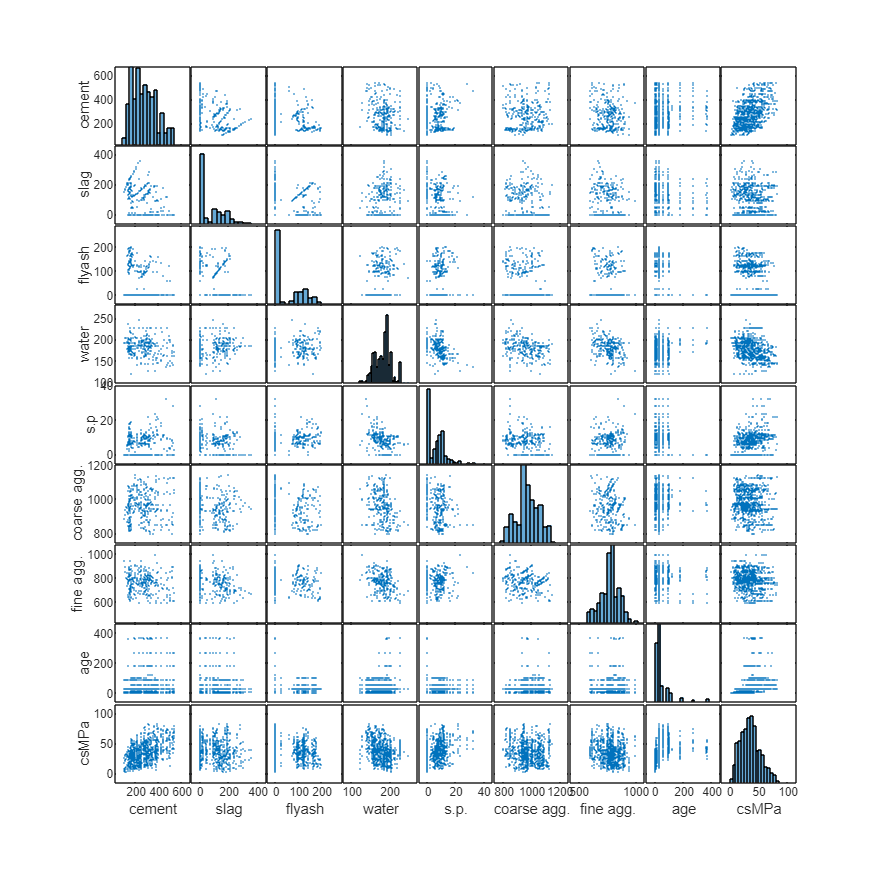

% Create pair plot
figure("Position", [0,0,2500,2500])
[~,ax,~,~,~] = plotmatrix(table2array(data));

% Set x and y labels
for i = 1:length(ax)
    if data.Properties.VariableNames{i} == "superplasticizer" 
        xlabel(ax(9,i), "s.p.", 'fontsize', 10)
        ylabel(ax(i,1), "s.p", 'fontsize', 10)
    elseif data.Properties.VariableNames{i} == "fineaggregate" 
        xlabel(ax(9,i), "fine agg.", 'fontsize', 10)
        ylabel(ax(i,1), "fine agg.", 'fontsize', 10)
    elseif data.Properties.VariableNames{i} == "coarseaggregate" 
        xlabel(ax(9,i), "coarse agg.", 'fontsize', 10)
        ylabel(ax(i,1), "coarse agg.", 'fontsize', 10)
    else
        xlabel(ax(9,i), data.Properties.VariableNames{i}, 'fontsize', 10)
        ylabel(ax(i,1), data.Properties.VariableNames{i}, 'fontsize', 10)
    end
end

Divide data between High and Low Strength

data.strength = categorical(data.csMPa >= 44, [0 1], {'Low' 'High'});
head(data)

    cement    slag     flyash    water    superplasticizer    coarseaggregate    fineaggregate    age    csMPa    strength
    ______    _____    ______    _____    ________________    _______________    _____________    ___    _____    ________

      540         0      0        162           2.5                 1040               676         28    79.99      High  
      540         0      0        162           2.5                 1055               676         28    61.89      High  
    332.5     142.5      0        228             0                  932               594        270    40.27      Low   
    332.5     142.5      0        228       

**Summary Statistics**

Generate summary information to [statistically describe the data](https://apmonitor.com/pds/index.php/Main/StatisticsMath).

summary(data)

Variables:

    cement: 1030×1 double

        Values:

            Min          102  
            Median     272.9  
            Max          540  

    slag: 1030×1 double

        Values:

            Min            0  
            Median        22  
            Max        359.4  

    flyash: 1030×1 double

        Values:

            Min            0  
            Median         0  
            Max        200.1  

    water: 1030×1 double

        Values:

            Min        121.8  
            Median       185  
            Max          247  

    superplasticizer: 1030×1 double

        Values:

            Min            0  
            Median       6.4  
            Max         32.2  

    coarseaggregate: 1030×1 double

        Values:

            Min          801  
            Median       968  
            Max         1145  

    fineaggregate: 1030×1

Check for balanced classification dataset ('high' and 'low' strength should have about equal amounts)

strengthCounts = tabulate(data.strength);
disp(strengthCounts);

    {'Low' }    {[736]}    {[71.4563]}
    {'High'}    {[294]}    {[28.5437]}



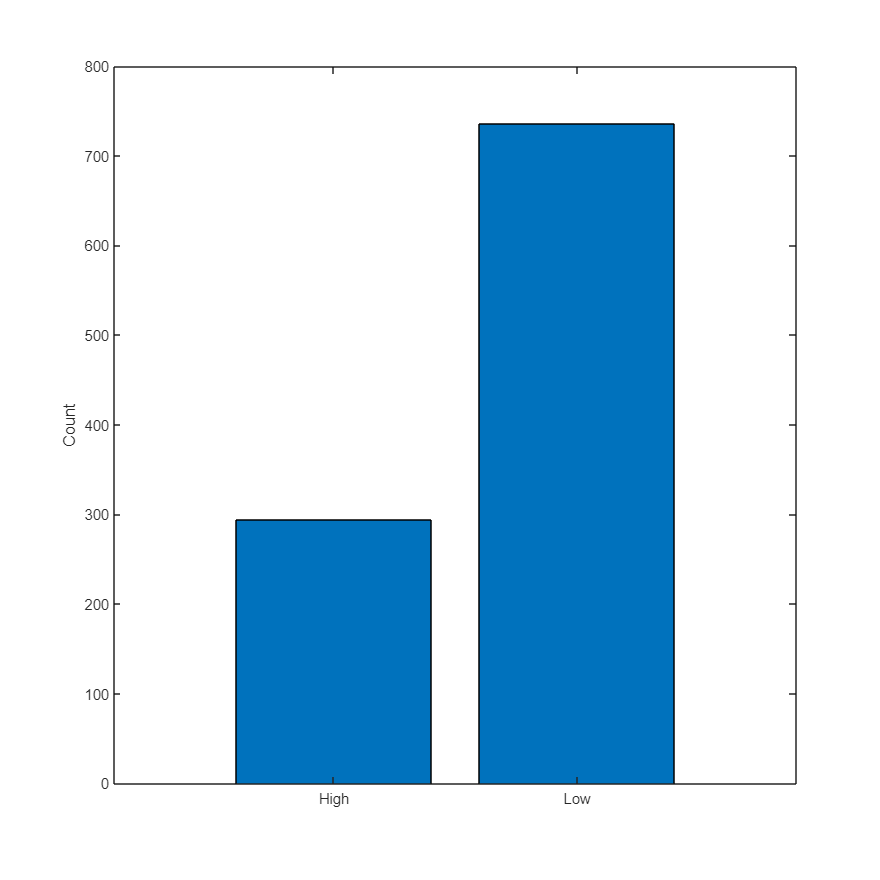

strengthCounts(:,2);
y1 = cell2mat(strengthCounts(1,2));
y2 = cell2mat(strengthCounts(2,2));
x = categorical({'Low' 'High'});
y = [y1 y2];
bar(x, y)
ylabel('Count');

**Convert String Categories (Text) to Binary (0 or 1)**

One-hot encoding translates character labels into a binary representation (0 or 1) for classification.

data.strength = categorical(data.csMPa >= 44, [0 1])

data = 1030×10 table
    cement    slag     flyash    water    superplasticizer    coarseaggregate    fineaggregate    age    csMPa    strength
    ______    _____    ______    _____    ________________    _______________    _____________    ___    _____    ________

      540         0      0        162           2.5                 1040               676         28    79.99       1    
      540         0      0        162           2.5                 1055               676         28    61.89       1    
    332.5     142.5      0        228             0                  932               594        270    40.27       0    
    332.5     142.5    

**Data Cleansing**

There is one row that contains an outlier. Identify the outlier with boxplots.

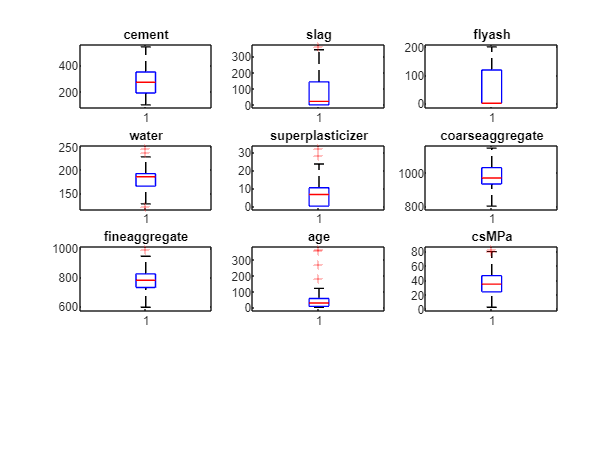

features = data(:,1:9).Properties.VariableNames;
figure();
for i = 1:numel(features)
    subplot(4, 3, i);
    boxplot(data.(features{i}));
    title(features{i});
end

View outliers

outliers = data((data.fineaggregate > 950) | (data.slag > 350), :);
disp(outliers)

    cement    slag     flyash    water    superplasticizer    coarseaggregate    fineaggregate    age    csMPa    strength
    ______    _____    ______    _____    ________________    _______________    _____________    ___    _____    ________

      375      93.8      0       126.6          23.4               852.1             992.6         3        29       0    
      375      93.8      0       126.6          23.4               852.1             992.6         7      45.7       1    
      375      93.8      0       126.6          23.4               852.1             992.6        28      56.7       1    
      375      93.8      0       126.6      

Remove rows that contain outliers.

data = data((data.fineaggregate < 950) & (data.slag < 350), :);
disp(data)

    cement    slag     flyash    water    superplasticizer    coarseaggregate    fineaggregate    age    csMPa    strength
    ______    _____    ______    _____    ________________    _______________    _____________    ___    _____    ________

      540         0        0       162           2.5                1040               676         28    79.99       1    
      540         0        0       162           2.5                1055               676         28    61.89       1    
    332.5     142.5        0       228             0                 932               594        270    40.27       0    
    332.5     142.5        0       228      

Verify that the outliers are removed with another box plot.

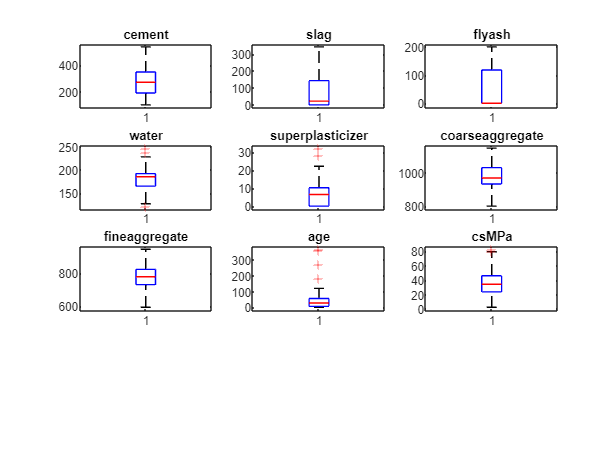

features = data(:,1:9).Properties.VariableNames;
figure();
for i = 1:numel(features)
    subplot(4, 3, i);
    boxplot(data.(features{i}));
    title(features{i});
end

**Data Correlation**

Generate a heat map of the data correlation.

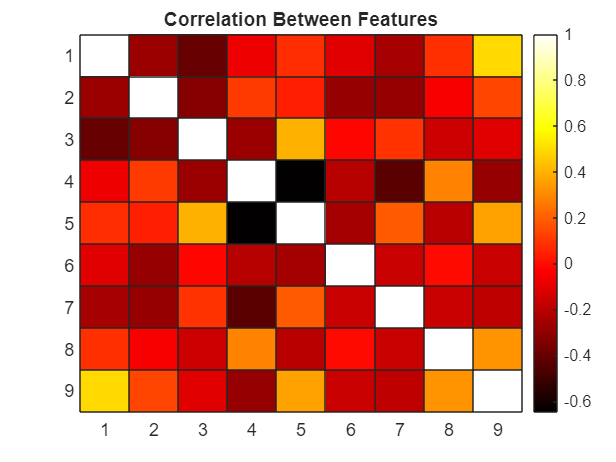

% data is a table
figure();
T = table2array(data(:,1:9));
correlation = corr(T);
heatmap(correlation, 'Colormap', hot, 'FontSize', 12, ...
    'Title', 'Correlation Between Features');

**Data Distributions and Pair Plot**

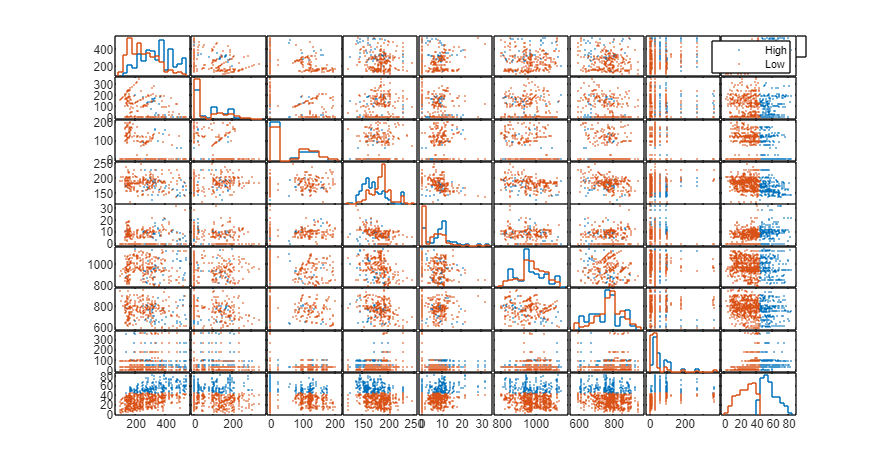

dpair = data;
dpair.strength = cellstr(string(dpair.strength));
dpair.strength(strcmp(dpair.strength, "1")) = {'High'};
dpair.strength(strcmp(dpair.strength, "0")) = {'Low'};

figure("Position", [0,0,2000,2000]);
gplotmatrix(table2array(dpair(:,1:9)), [], dpair.strength)
legend('Location', 'bestoutside');

## Part 2: Classification

Train and test a classifier to distinguish between high and low strength concrete. Test at least 8 classifiers of your choice. Recommend a best classifier among the 8 that are tested.

**Divide Input Features (X) and Output Label (y)**

Divide the data into sets that contain the input features (X) and output label (y=csMPa). Save data feature columns with X_names=list(data.columns) and remove strength with X_names.remove('strength') and remove csMPa with X_names.remove('csMPa').

y_name = 'strength';
X_names = data.Properties.VariableNames;
X_names(strcmp(X_names,y_name)) = [];
X_names(strcmp(X_names,'csMPa')) = [];
disp(X_names);

    {'cement'}    {'slag'}    {'flyash'}    {'water'}    {'superplasticizer'}    {'coarseaggregate'}    {'fineaggregate'}    {'age'}



X = data(:,X_names);
y = data(:,y_name);

**Data scaling**

Scale the input features with a StandardScaler or a MinMaxScaler. Why do classifiers return an error if the output label is scaled with StandardScaler?

Xs = normalize(X)

Xs = 1023×8 table
     cement       slag       flyash      water      superplasticizer    coarseaggregate    fineaggregate      age   
    ________    ________    ________    ________    ________________    _______________    _____________    ________

      2.4771    -0.85527    -0.85172    -0.94073        -0.61934            0.85665           -1.2271       -0.28044
      2.4771    -0.85527    -0.85172    -0.94073        -0.61934             1.0501           -1.2271       -0.28044
     0.49416     0.80878    -0.85172      2.1906         -1.0456           -0.53608           -2.2673          3.541
     0.49416     0.80878    -0.85172      2.1906         -1.0456           -0.53608           -2.2673         5.0411
    -0.

Answer: The output label should not be scaled because it needs to be categorical data as an integer instead of a continuous real number.

**Train / Test Split**

Randomly select values that split the data into a train (80%) and test (20%) set by using cvpartition.

c = cvpartition(size(Xs,1),'Holdout',0.2);
X_train = Xs(training(c),:);
X_test = Xs(test(c),:);
y_train = y(training(c),:);
y_test = y(test(c),:);
disp([num2str(height(X_train)) ' ' num2str(height(X_test))])

819 204


**Evaluate the Best Features**

Use  to evaluate the best features for the classifier.

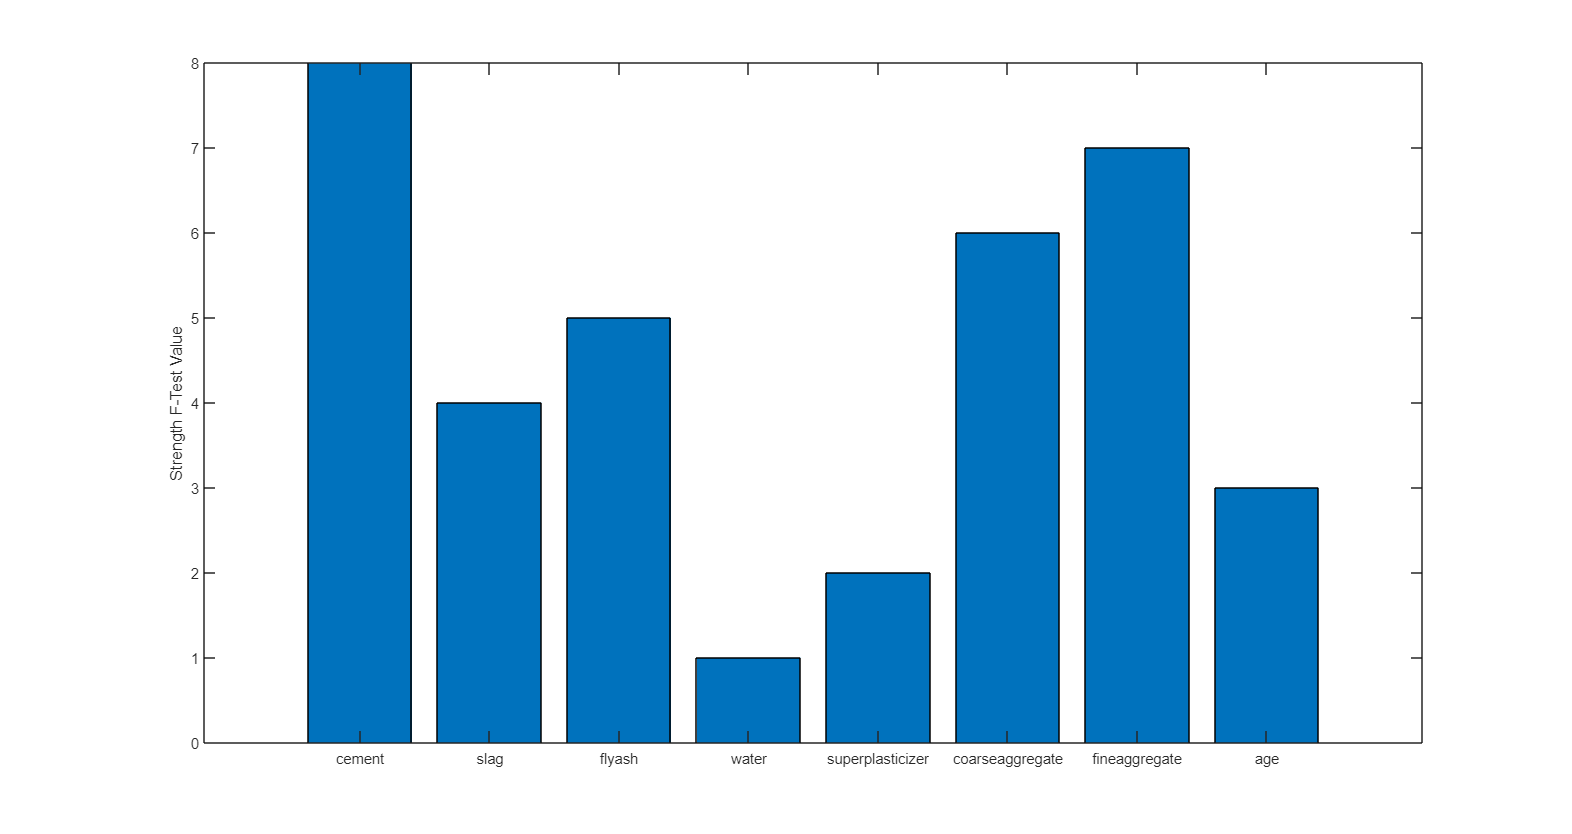

y_v = table2array(y_train);
% scores = fscchi2(X_train,y_train)

scores = fsrftest(X_train, double(y_v));
bar(scores);
xticklabels(X_names);
ylabel('Strength F-Test Value');

**Train (fit) and Test Classification with Logistic Regression**

% perform logistic regression
B = mnrfit(table2array(X_train), table2array(y_train));
y_pred = mnrval(B, table2array(X_test));
[~, y_pred] = max(y_pred, [], 2);

% calculate confusion matrix
y_test_v = double(table2array(y_test));
C = confusionmat(y_test_v, y_pred);

% plot confusion matrix using heatmap
figure('Visible','on')
heatmap(C);
xlabel('Predicted Class');
ylabel('True Class');
title('Confusion Matrix');

**Train 8 Classifiers**

Create 8 classifier objects and train.

y_train_v = double(table2array(y_train));
nb = fitcnb(X_train, y_train);
dt = fitctree(X_train, y_train);
knn = fitcknn(X_train, y_train);
svm = fitcsvm(X_train, y_train);
nn = fitcnet(X_train, y_train, 'Standardize', true, 'LayerSizes', 10);
sgd = fitcsvm(X_train, y_train, 'Solver', 'smo', 'Standardize', true);
lr = fitglm(table2array(X_train), table2array(y_train), 'Distribution', 'binomial', 'Link', 'logit');
t = templateTree('NumVariablesToSample','all','PredictorSelection','interaction-curvature','Surrogate','on');
rfm = fitensemble(X_train, y_train_v, 'LogitBoost', 200, t);

clsfrs = {nb, 'Naive Bayes';
          dt, 'Decision Tree';
          knn, 'K Nearest Neighbors';
          svm, 'Support Vector Machine';
          sgd, 'Stochastic Gradient Descent';
          nn, 'Neural Network';
          lr, 'Logistic Regression';
          rfm, 'Random Forest Classifier';};

for i = 1:size(clsfrs, 1)
    name = clsfrs{i, 2};
    clf = fitcnb(X_train, y_train);
end

**Classifier Evaluation**

Report the confusion matrix on the test set for each classifier. Discuss the performance of each. A confusion matrix shows correct classification (diagonals) and incorrect classification (off-diagonals) groups from the test set. Generate a confusion matrix for each classifier.

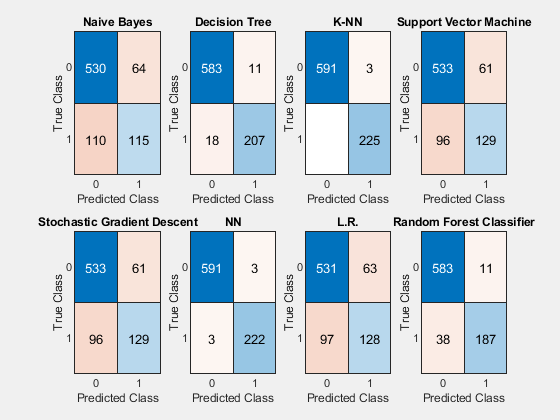

figure('Visible','on')
for i = 1:6
    subplot(2, 4, i);
    C_labels = resubPredict(clsfrs{i, 1});
    confusionchart(table2array(y_train), C_labels)
    if clsfrs{i,2} == "K Nearest Neighbors"
        title("K-NN")
    elseif clsfrs{i,2} == "Neural Network"
        title("NN")
    else
        title(clsfrs{i,2});
    end
end

subplot(2,4,7)
options = statset('UseParallel',true);
C_lr = fitcecoc(X_train, y_train);
CV_lr = crossval(C_lr, 'Options',options);
predict2 = kfoldPredict(CV_lr,'Options',options);
y_train_a = table2array(y_train);
confusionchart(y_train_a, predict2);
title("L.R.");

subplot(2,4,8)
C3_labels = resubPredict(rfm);
confusionchart(table2array(y_train), categorical(C3_labels-1));
title(clsfrs{8,2})

## Part 3: Regression

Develop a regression model to predict Tension Strength (MPa). Compare predicted concrete strength with the regression model.

**Regression Fit**

Use 3 regression methods. Use Linear Regression, Neural Network (Deep Learning), and another regression method of your choice. Discuss the performance of each. Possible regression methods are:

- Linear Regression

- Neural Network (Deep Learning)

- K-Nearest Neighbors

- Support Vector Regressor

y2 = data(:,'csMPa');
c2 = cvpartition(size(Xs,1),'Holdout',0.2);
X_train = Xs(training(c2),:);
X_test = Xs(test(c2),:);
y_train = y2(training(c2),:);
y_test = y2(test(c2),:);
disp([num2str(height(X_train)) ' ' num2str(height(X_test))])

819 204


y_train_v = double(table2array(y_train));
y_test_v = double(table2array(y_test));
X_train_m = table2array(X_train);
lin= fitglm(X_train_m, y_train_v);
sv= fitrsvm(X_train, y_train_v);
nn= fitrnet(X_train, y_train_v, 'LayerSizes',[3,5,3],'Standardize', 1);
lin2 = fitglm(table2array(X_test), double(table2array(y_test)));
sv2= fitrsvm(X_test, double(table2array(y_test)));
nn2= fitrnet(X_test, double(table2array(y_test)), 'LayerSizes',[3,5,3],'Standardize',1);

regress = {lin, 'Linear Regression';
          sv, 'Support Vector Regression';
          nn, 'Nerual Network';};


X_train_new = renamevars(X_train,["cement","slag","flyash","water","superplasticizer","coarseaggregate","fineaggregate","age"], ["x1","x2","x3","x4","x5","x6","x7","x8"]);
X_test_new = renamevars(X_test,["cement","slag","flyash","water","superplasticizer","coarseaggregate","fineaggregate","age"], ["x1","x2","x3","x4","x5","x6","x7","x8"]);

lin_predict = predict(lin, X_train_new);
lin_predict_t = predict(lin2, X_test_new);
nn_predict = predict(nn, X_train);
nn_predict_t = predict(nn2, X_test);
sv_predict = predict(sv, X_train);
sv_predict_t = predict(sv2, X_test);

**Validation**

Report the correlation coefficient $R^2$ for the train and test sets.

Train Set

lin_rsq = lin.Rsquared.Ordinary

lin_rsq = 0.6170

sv_resid = y_train_v - sv_predict;
sv_SSresid = sum(sv_resid.^2);
sv_SStotal = (length(y_train_v)-1)*var(y_train_v);
sv_rsq = 1 - sv_SSresid/sv_SStotal

sv_rsq = 0.6028

nn_resid = y_train_v - nn_predict;
nn_SSresid = sum(nn_resid.^2);
nn_SStotal = (length(y_train_v)-1)*var(y_train_v);
nn_rsq = 1 - nn_SSresid/nn_SStotal

nn_rsq = 0.8501

Test Set

lin2.Rsquared.Ordinary

ans = 0.6267

sv2_resid = y_test_v - sv_predict_t;
sv2_SSresid = sum(sv2_resid.^2);
sv2_SStotal = (length(y_test_v)-1)*var(y_test_v);
sv2_rsq = 1 - sv2_SSresid/sv2_SStotal

sv2_rsq = 0.6099

nn2_resid = y_test_v - nn_predict_t;
nn2_SSresid = sum(nn2_resid.^2);
nn2_SStotal = (length(y_test_v)-1)*var(y_test_v);
nn2_rsq = 1 - nn2_SSresid/nn2_SStotal

nn2_rsq = 0.8563

**Parity Plot**

A parity plot is a scatter plot with predicted versus measured. A parity plot of the training and test data is a good way to see the overall fit of tension strength.

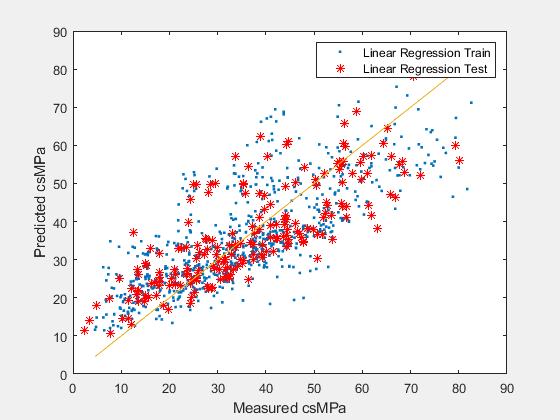

figure('Visible','on')
plot(y_train_v, lin_predict, ".")
hold on
plot(y_test_v, lin_predict_t, "r*")
plot(y_train_v, y_train_v)
xlabel("Measured csMPa")
ylabel("Predicted csMPa")
legend('Linear Regression Train', 'Linear Regression Test')
hold off

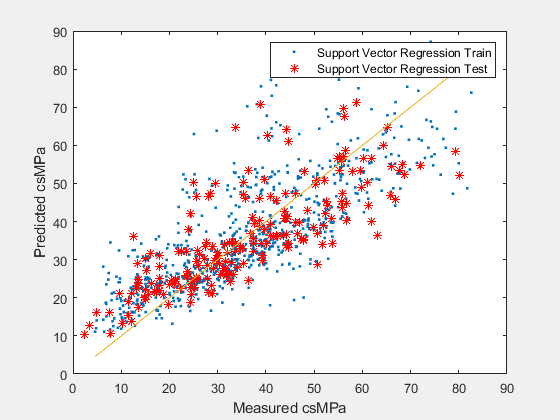

plot(y_train_v, sv_predict, ".")
hold on
plot(y_test_v, sv_predict_t, "r*")
plot(y_train_v, y_train_v)
xlabel("Measured csMPa")
ylabel("Predicted csMPa")
legend('Support Vector Regression Train', 'Support Vector Regression Test')
hold off

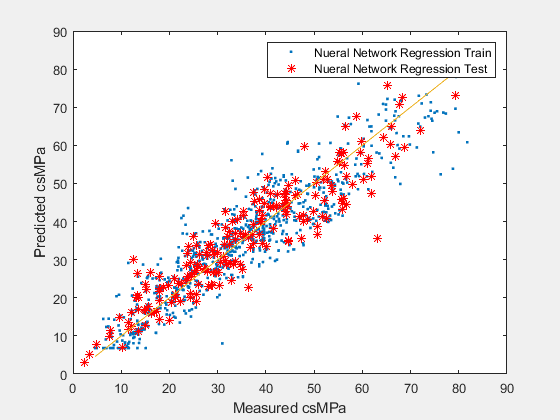

plot(y_train_v, nn_predict, ".")
hold on 
plot(y_test_v, nn_predict_t, "r*")
plot(y_train_v, y_train_v)
xlabel("Measured csMPa")
ylabel("Predicted csMPa")
legend('Nueral Network Regression Train', 'Nueral Network Regression Test')
hold off

From these graphs above, you can see that the various linear regression methods perform well at predicting the concrete strength based on its properties. The closer the values are to the straight line shows the more accurate the model is at predicting the strength of the concrete.